#### Fintech Final Project, Group 2

*Bucci Teo*

*Cipriani Filippo*

*Corbo Gabriele*

*Fabroni Davide*

*Lucchini Marco*

# Estimating Clients' Needs

## Aim: supervised classification of clients and association with his/her preferred product

Our goal is to provide a tool for a financial advisor which supports him in suggesting financial products to his clients.

We intend to estimate some **investments needs **for these customers using **Machine Learning** techniques: we use a bagged tree and a AdaBoostM1, fine-tuned with bayesian optimization. After that, we match the client with his/her preferred product.

### Datasets

The first dataset is a table called `Needs`, with some relevant features and two responses:

- `AccumulationInvest` which is about **Accumulation investing**, typically using dollar-cost averaging (you invest small amounts of your money at certain intervals over the course of time); the response is boolean: 1 = high propensity, 0 = low propensity;

- `IncomeInvest` which is about **Income investing**, typically through lump sum investing (one shot); the response is boolean: 1 = high propensity, 0 = low propensity.

The second dataset is called `Products` and contains some products (funds, segregated accounts, unit-linked), their **type** (1 = Accumulation, 0 = Income), and their **risk level** (normalized in the range [0,1]).

load('Needs.mat')

### **Data transformation of Wealth and Income**

Wealth and Income follow a power law, so it's better to apply some transformation rule.

We chose the **Box Cox** transormation, because it's the one that give us the distribution closer to a normal.

We decided to use an addidional feature, called **Financial Status** as a combination of financial education and wealth: we chose this variable because using R we tried many linear models to predict the risk variable associated with each client, and we saw that this particular trasformation of feature carried a lot of information.

We will cover this part in more detail in the section **Predicting Risk Propension**.

Data = Needs; % renaming
Data.FinancialStatus = Data.FinancialEducation.*log(Data.Wealth)

Data = 5000×11 table
    ID    Age    Gender    FamilyMembers    FinancialEducation    RiskPropensity    Income    Wealth    IncomeInvestment    AccumulationInvestment    FinancialStatus
    __    ___    ______    _____________    __________________    ______________    ______    ______    ________________    ______________________    _______________

    1     60       0             2               0.22868             0.23335        68.182     53.26           0                      1                   0.90906    
    2     78       0             2               0.35892             0.17091        21.808    135.55      

[boxWealth,p] = boxcox(Data.Wealth);
p

p = 0.1341

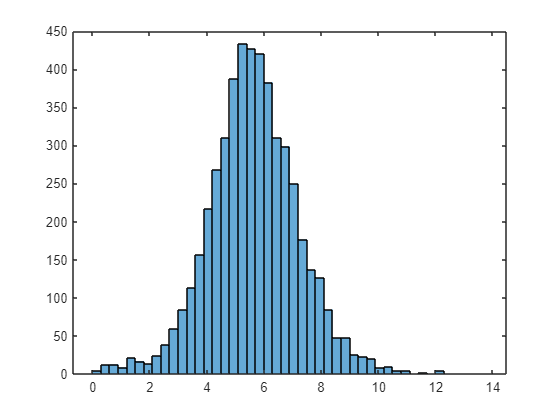

histogram(boxWealth);

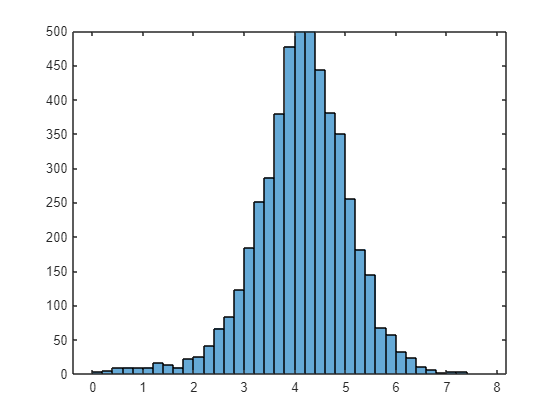

histogram(log(Data.Wealth))

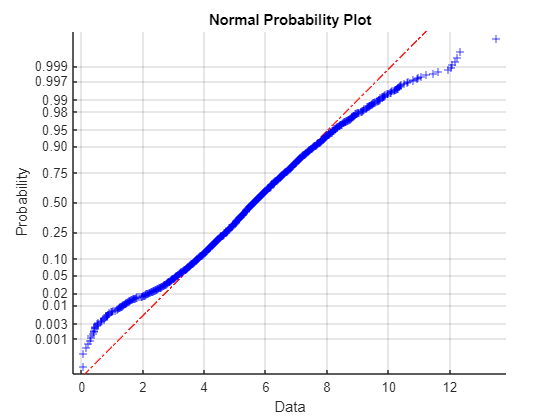

normplot(boxWealth) % we chose boxWealth

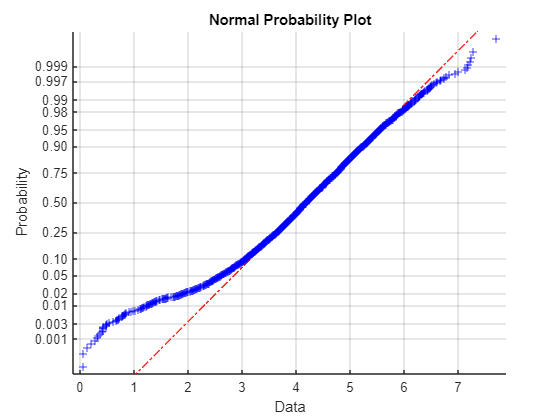

normplot(log(Data.Wealth))

[boxIncome,p] = boxcox(Data.Income);
p

p = 0.3026

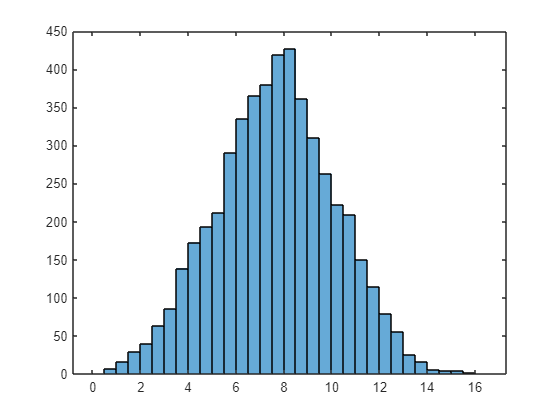

histogram(boxIncome);

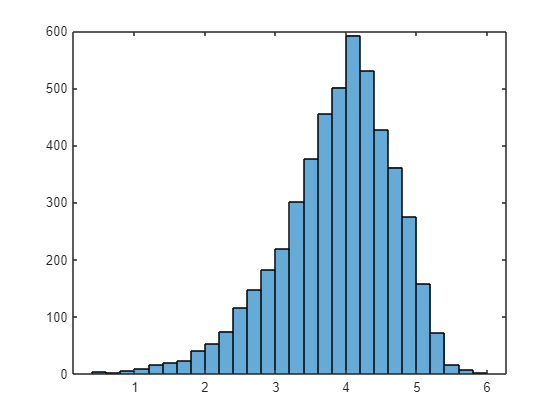

histogram(log(Data.Income))

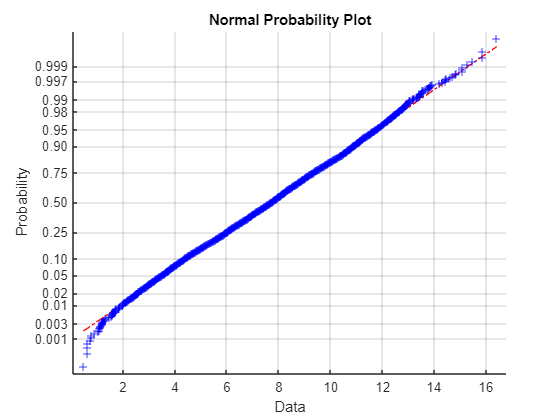

normplot(boxIncome) % we chose boxIncome

### Data scaling

We will use the **min/max rescaling** approach in order to make our data comparable before applying the machine learning techniques.

X = [rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) ...
    rescale(Data.FinancialEducation) rescale(Data.RiskPropensity) ...
    rescale(boxIncome) rescale(boxWealth) rescale(Data.FinancialStatus)];

### Train-test split and Permutation

We divide data in the training sample and test sample. The proportion training-test we use is 75%-25%;

nObs = size(Data, 1);
rng(10) % set random seed
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
train = 0.75;
cross = 0;

nObsTrain = round(train*nObs);
nObsCross = round(cross*nObs);

XTrain = X(1:nObsTrain, :);
XCross = X((nObsTrain+1):(nObsTrain+nObsCross), :);
XTest = X(nObsTrain+1+nObsCross:end, :);

% Here we add the same permutation of X to Y
YInc = Data.IncomeInvestment;
YInc = YInc(idxPermutation);

yInvIncTrain = YInc(1:nObsTrain);
yInvIncCross = YInc((nObsTrain+1):(nObsTrain+nObsCross));
yInvIncTest = YInc(nObsTrain+nObsCross+1:end);

YAcc = Data.AccumulationInvestment;
YAcc = YAcc(idxPermutation);

yInvAccTrain = YAcc(1:nObsTrain);
yInvAccCross = YAcc((nObsTrain+1):(nObsTrain+nObsCross));
yInvAccTest = YAcc(nObsTrain+nObsCross+1:end);

% Creation of the tables
varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk',...
             'Income', 'Wealth','FinancialStatus'};

XTrainTable = table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4),...
                    XTrain(:,5), XTrain(:,6), XTrain(:,7), XTrain(:,8),...
                    'VariableNames',varNames);

XTestTable = table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4),...
                   XTest(:,5), XTest(:,6), XTest(:,7), XTest(:,8),...
                   'VariableNames',varNames);

### Predicting RiskPropensity

We think that estimating the parameter risk is a critical step because it’s quite unrealistic that a customer knows by himself how much he wants to risk in a 0-1 scale: for example to avoid this problem the popular roboadvisor [Moneyfarm](https://www.moneyfarm.com/) uses a short survey to estimate the parameter.

We thought of using the **MiFID** survey (acronym for Directive on Markets in Financial Instruments) which aims to collect as much information as possible related to the knowledge and experience of a client's investments, investment objectives and financial situation. However, in the original dataset we didn't have all the information needed by the MiFID, but only some, thus we decided to go with a hybrid approach. Using the **Regression Learner**, we found out that the **Linear Regression** model was accurate enough at predicting risk based on our regressors.

We used all the parameters except the gender, since we noticed it wasn't significant in the model.

Xtopred = X(1:nObsTrain, :); % selecting risk predictors
Xtopred(:,5) = []; % removing RiskPropensity from the predictors
risk = X(1:nObsTrain, 5); 

XtopredTest = X(nObsTrain+nObsCross+1:end, :);
XtopredTest(:,5) = [];
riskTest = X(nObsTrain+nObsCross+1:end, 5);

% Linear Regression
RiskPred = fitlm(Xtopred,risk)

RiskPred = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)       0.13869     0.016848      8.2318    2.5201e-16
    x1               -0.32087     0.016829     -19.066     2.013e-77
    x2             0.00024763    0.0040256    0.061513       0.95095
    x3               0.051242     0.010762      4.7612    1.9973e-06
    x4                0.53013     0.044845      11.822    1.0987e-31
    x5              -0.094593     0.017439     -5.4242    6.1888e-08
    x6                0.41875     0.048154      8.6961     5.057e-18
    x7   

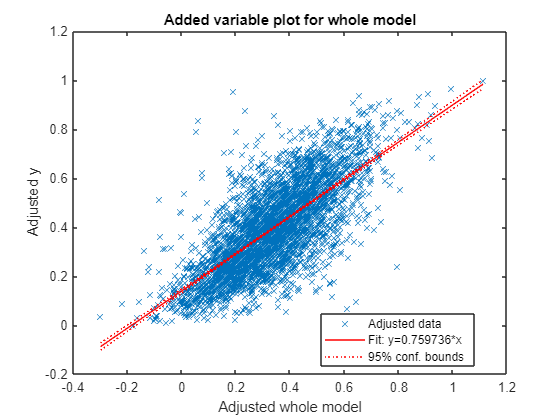

plot(RiskPred) % plot of adjusted y

Estimation of the errors

yfit = predict(RiskPred, XtopredTest);
MAE = mean(abs(yfit-riskTest));
adjMAE = MAE/range(riskTest);
errors = [MAE adjMAE]

errors =     0.0977    0.1055


Xpredicted = X;
Xpredicted(:,5) = [];
yfit = predict(RiskPred, Xpredicted); % predicting risk using the whole dataset

X(:,5) = yfit; % adding predicted risk to x

### Classification models

We follow the financial advisory best practice to refine the process:

- accumulation investment products are mainly intended for relatively young people who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older;

- since the Y's derive from the behavior of financial advisors who hopefully follow this practice, an interesting variable is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture we try to eliminate family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important). Even risk propensity shouldn't be so important in order to estimate financial needs (it's important in order to choose the right risk level given the product).

xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth'};

IncomeWealthRatio = zeros(nObs,1);
% >10 because of an outlier
IncomeWealthRatio(Data.Wealth>10) = boxIncome(Data.Wealth>10)./boxWealth(Data.Wealth>10);

Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) ...
          rescale(Data.FinancialEducation) boxIncome boxWealth];
Xsmall = Xsmall(idxPermutation,:);

Back to the classification learner to see what happens: we create a smaller data table.

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable = table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), ...
                         XsmallTrain(:,4), XsmallTrain(:,5), ...
                         'VariableNames', xnames);

### Fitting the optimized ensemble model

First of all, we prepare our model.

We fit an optimal ensemble of learners for classification: we automatically optimize ensemble hyperparameters using the function `fitcensemble`. It finds hyperparameters that minimize k-fold cross-validation loss (with K=5) by using automatic hyperparameter optimization. As we specify `'OptimizeHyperparameters'`, the function finds optimal parameters automatically using Bayesian optimization.

#### Accumulation

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |       0.288 |      10.199 |       0.288 |       0.288 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |         0.2 |      10.587 |         0.2 |     0.20502 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Best   |     0.19253 |      6.9119 |     0.19253 |     0.19535 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2264 |      7.9192 |     0.19253 |   

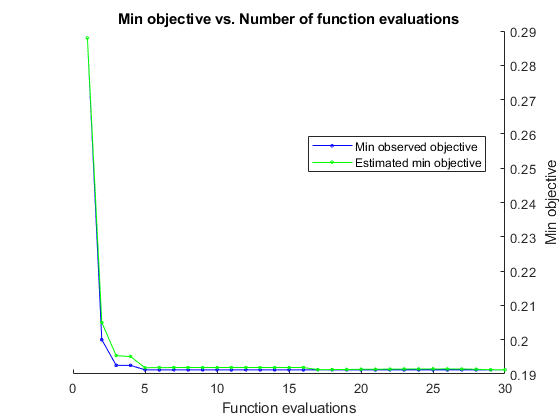


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 567.6997 seconds
Total objective function evaluation time: 523.3614

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             33               NaN           36     

Observed objective function value = 0.1912
Estimated objective function value = 0.19125
Function evaluation time = 8.4604

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_acc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 33
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: 

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain, ...
    'OptimizeHyperparameters','auto', ...
    'Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

#### Income

For the Income we add a cost matrix in order to penalize the first type error.

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.25947 |      9.8578 |     0.25947 |     0.25947 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |     0.20293 |      7.8018 |     0.20293 |     0.20616 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Accept |     0.22373 |      1.4248 |     0.20293 |     0.20506 |          Bag |           12 |            - |           18 |
|    4 | Best   |     0.18853 |      1.4955 |     0.18853 |   

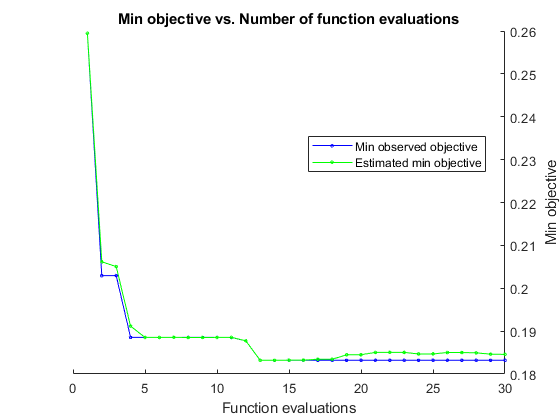


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 325.4636 seconds
Total objective function evaluation time: 300.524

Best observed feasible point:
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________    ___________

    LogitBoost           170           0.019744          1     

Observed objective function value = 0.1832
Estimated objective function value = 0.18458
Function evaluation time = 14.2102

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    ________

MdlOptimum_inc =   ClassificationEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 170
                               Method: 'LogitBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [170×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, <a href=

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_inc = fitcensemble(XsmallTrainTable, yInvIncTrain, ...
    'Cost',[0 1;2 0], ...
    'OptimizeHyperparameters','auto', ...
    'Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

We go for a **Bagged** **Tree** for the Accumulation products and a **AdaBoostM1** for the Income products.

Saving the models for later use.

save("model_acc.mat","MdlOptimum_acc");
save("model_inc.mat","MdlOptimum_inc");

load("model_acc.mat", "MdlOptimum_acc")
load("model_inc.mat", "MdlOptimum_inc")

## Prediction

From each ensemble classifier, `MdlOptimum_acc` and `MdlOptimum_inc`, we retrieve:

- predicted labels;

- scores (the confidence that an observation originates from a specific class; the higher the score, the higher the confidence;  `Bag` scores range from `0` to `1`: closer they are to 1 better is the performance of the classification model.

We examine scores,which are probabilities averaged over all the trees in the ensemble, in order to understand how strong is the model conviction.

We transformed the score of the Income model in a probability density function using the `ScoreTransform` function, so that the scores range is [0,1].

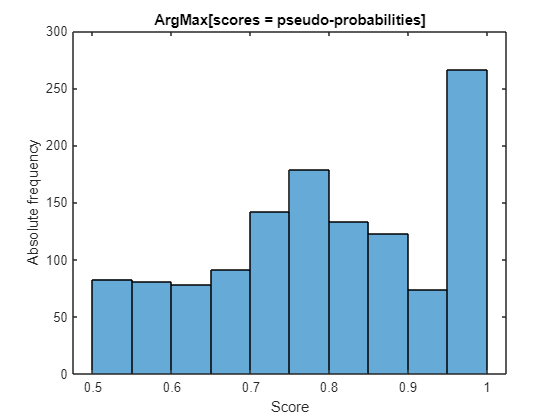

[labels_acc,scores_acc] = predict(MdlOptimum_acc, XsmallTest);
figure
histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

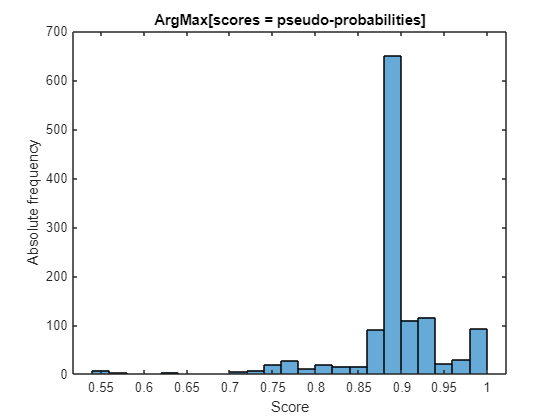


MdlOptimum_inc.ScoreTransform = 'doublelogit';
[labels_inc,scores_inc] = predict(MdlOptimum_inc,XsmallTest);
figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

We observe that most scores are close to 1, therefore the model has a strong convinction of its predictions.

### Analysis of the results of the model

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the need of clients to their true value.

#### Accumulation

tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));
prec_acc = tp_acc / (tp_acc + fp_acc)

prec_acc = 0.8857

rec_acc = tp_acc / (tp_acc + fn_acc)

rec_acc = 0.7678

F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

F1_acc = 0.8226

#### Income

tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));
fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));
prec_inc = tp_inc / (tp_inc + fp_inc)

prec_inc = 0.8933

rec_inc = tp_inc / (tp_inc + fn_inc)

rec_inc = 0.5618

F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

F1_inc = 0.6898

In both cases the results indicate that the model accurately classifies Accumulation and Income need, since precision, recall and F1 score are quite close to 1.

### ROC curve

#### Accumulation

[X_acc, Y_acc, T_acc, AUC_acc, OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);
AUC_acc % very good value of AUC

AUC_acc = 0.8770

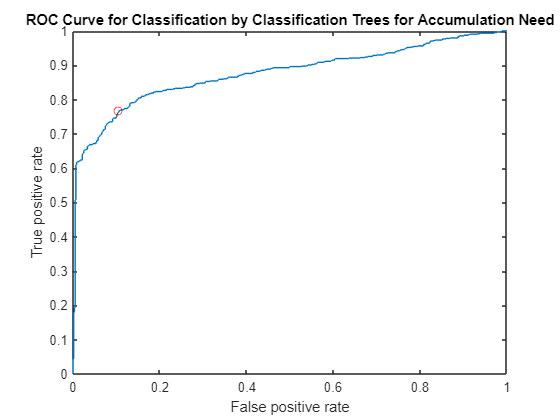

plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Accumulation Need')
hold off

Optimal operating point accumulation

OPTROCPT_acc

OPTROCPT_acc =     0.1060    0.7678


Threshold of the optimal operating point

T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))

ans = 0.5002

#### Income

[X_inc, Y_inc, T_inc, AUC_inc, OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
AUC_inc % very good value of AUC

AUC_inc = 0.7775

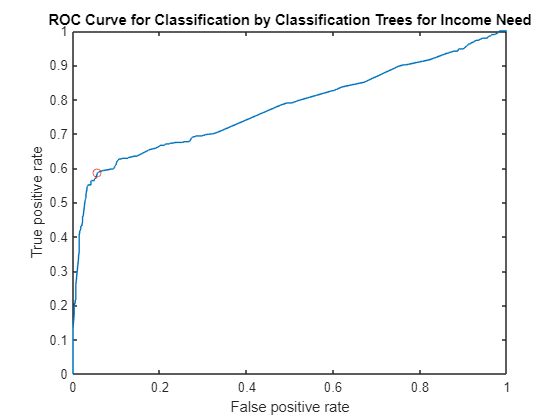

plot(X_inc,Y_inc)
hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Income Need')
hold off

Optimal operating point accumulation

OPTROCPT_inc

OPTROCPT_inc =     0.0569    0.5870


Threshold of the optimal operating point

T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

ans = 0.2590

The ROC curves show the goodness-of-fit of the model. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curves confirm that our models provide an accurate classification. Moreover, the value of the AUC is very close to 1 in both cases.

We observe that the classification of Accumulation needs is a bit more accurate than the Income ones.

### **Confusion matrices**

#### **Accumulation**

Specify `'RowSummary'` as `'row-normalized'` to display the true positive rates (TPR) and false positive rates (FPR) in the row summary. Also, specify `'ColumnSummary'` as `'column-normalized'` to display the positive predictive values and false discovery rates in the column summary.

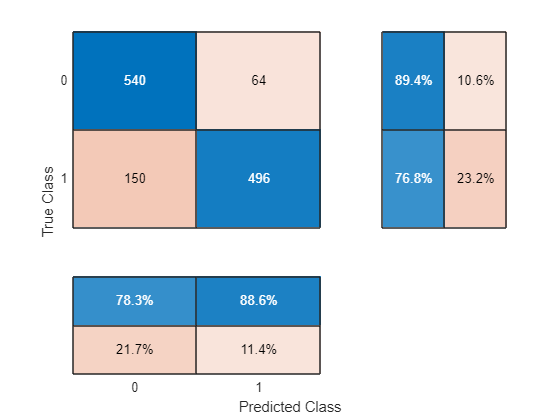

confusionchart(yInvAccTest, labels_acc,...
               'RowSummary','row-normalized',...
               'ColumnSummary','column-normalized');

#### Income

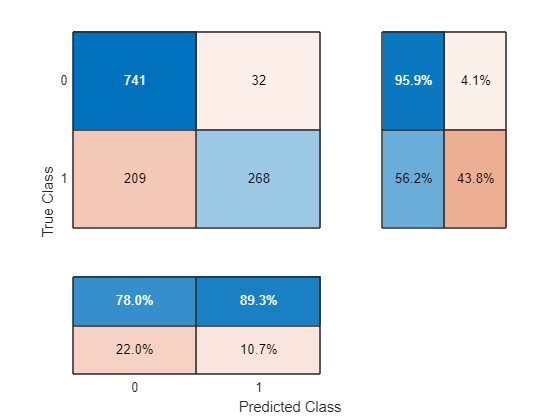

confusionchart(yInvIncTest, labels_inc,...
               'RowSummary','row-normalized',...
               'ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

## Recommending products

Now we generate the personalized recommendation for both the Accumulation products (that is, Products.Type==1) and for the Income Products (that is, Products.Type==0).

We adopt the following rules, for each client:

- **estimating the risk propensity**

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting a list of products**, ranked based on a decreasing risk.

The recommendation system is implemented in a **Streamlit** app using **sklearn**.